# Esercizi vari sulla propagazione dell'incertezza 

## Generazione di popolazioni di errori, e calcolo di WCU, SU, EU dalle popolazioni generate

Acronimi:

- WCU = worst-case uncertainty = incertezza di caso peggiore

- SU = standard uncertainty = incertezza standard (anche "incertezza tipo")

- EU = expanded uncertainty = incertezza estesa

% Con le informazioni fornite, generare un vettore riga di Nsim errori con la pdf appropriata, per
% ognuno dei casi contemplati dal quesito.
% Si calcoli poi WCU, SU, EU dalla popolazione di errori generata, per ognuno dei casi.
%
% Nota:
% 1) L'essenza del quesito sta nel capire qual è la pdf dell'errore in base alle informazioni disponibili;
% 2) Individuata la pdf, bisogna saper generare la popolazione degli errori usando le istruzioni
% rand, randn, oppure unifrnd, normrnd, ecc.

% Dati
clear
U1 = 1 % WCU; non sappiamo altro (caso 1)

U1 = 1

u2 = 1 % SU; non sappiamo altro (caso 2)

u2 = 1

Ucp3 = 1 % EU; non sappiamo altro (caso (3)

Ucp3 = 1

U4 = 1 % WCU; la distribuzione è triangolare (caso 4)

U4 = 1

U5 = 1 % WCU; la distribuzione è arcoseno (caso 5)

U5 = 1

U6 = 1 % WCU; la distribuzione è a campana, convoluzione di tre distribuzioni uniformi identiche (caso 6)

U6 = 1


cp = 0.95 % probabilità di copertura delle EU

cp = 0.9500

Nsim = 1e6 % numero di elementi dei vettori di errori (stiamo facendo una simulazione Monte Carlo di errori)

Nsim = 1000000


% Domande
% e1, e2, e3, ecc.: per ogni caso calcolare il vettore riga di Nsim errori, secondo la pdf appropriata
% U1_sim, u1_sim, Ucp1_sim; U2_sim, u2_sim, Ucp2_sim; ecc.: per ogni caso calcolare WCU, SU, EU in base a e1, e2, ecc.

% Per ogni caso, tracciare un istogramma pdf degli errori, con indicate le WCU, SU, EU calcolate

### Soluzione

1) E' nota la sola WCU: *la pdf è uniforme (rettangolare)*

% e1 = unifrnd(-U1,U1,[1,Nsim]);
e1 = (rand([1,Nsim])-0.5)*2*U1; % equivalente

U1_sim = max(abs(e1)) % WCU calcolata dagli errori simulati

U1_sim = 1.0000

u1_sim = std(e1) % SU calcolata dagli errori simulati

u1_sim = 0.5771

Ucp1_sim = quantile(e1, (1+cp)/2) % UE calcolata dagli errori simulati

Ucp1_sim = 0.9501

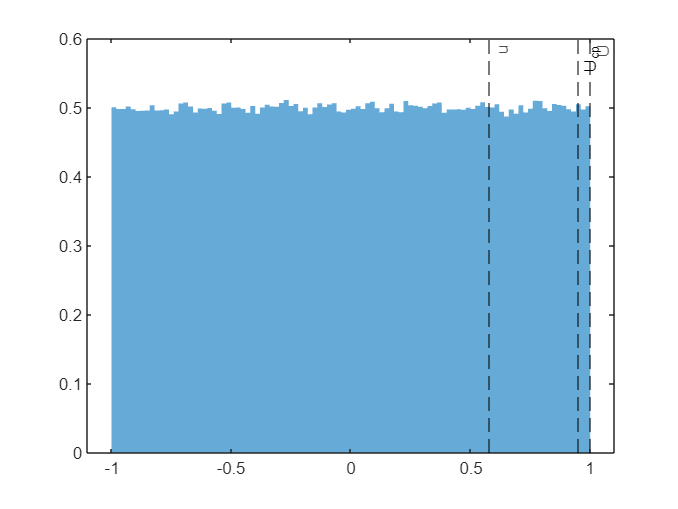

histogram(e1,'Normalization','pdf','EdgeColor','none')
xline(u1_sim,'--k','u')
xline(Ucp1_sim,'--k','U_{cp}')
xline(U1_sim,'--k','U')

2) E' nota la sola SU: *la pdf è gaussiana*

% e2 = normrnd(0,u2,[1,Nsim]);
e2 = randn([1,Nsim])*u2; % equivalente

U2_sim = max(abs(e2)) % naturalmente la WCU "vera" è +inf

U2_sim = 4.8056

u2_sim = std(e2)

u2_sim = 0.9994

Ucp2_sim = quantile(e2, (1+cp)/2)

Ucp2_sim = 1.9598

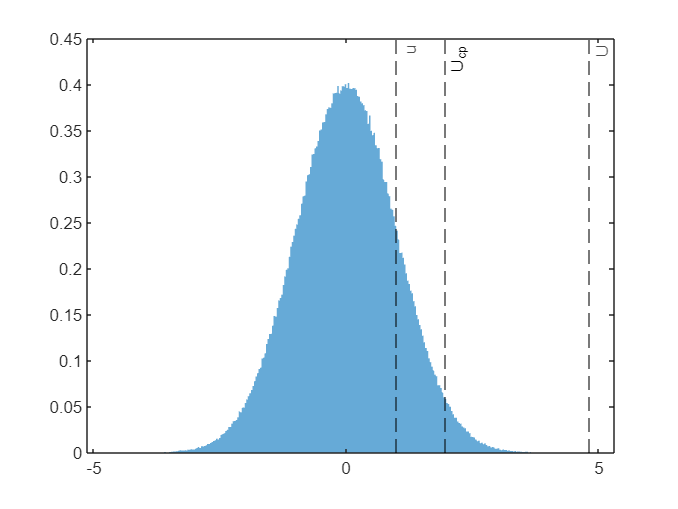

histogram(e2,'Normalization','pdf','EdgeColor','none')
xline(u2_sim,'--k','u')
xline(Ucp2_sim,'--k','U_{cp}')
xline(U2_sim,'--k','U')

3) E' nota la sola EU: *la pdf è gaussiana, dalla EU si ricava la SU*

kp = norminv((1+cp)/2) % fattore di copertura

kp = 1.9600

u3 = Ucp3/kp

u3 = 0.5102

% e3 = normrnd(0,u3,[1,Nsim]); % equivalente
e3 = randn([1,Nsim])*u3;

U3_sim = max(abs(e3)) % naturalmente la WCU "vera" è +inf

U3_sim = 2.5844

u3_sim = std(e3)

u3_sim = 0.5102

Ucp3_sim = quantile(e3, (1+cp)/2)

Ucp3_sim = 1.0024

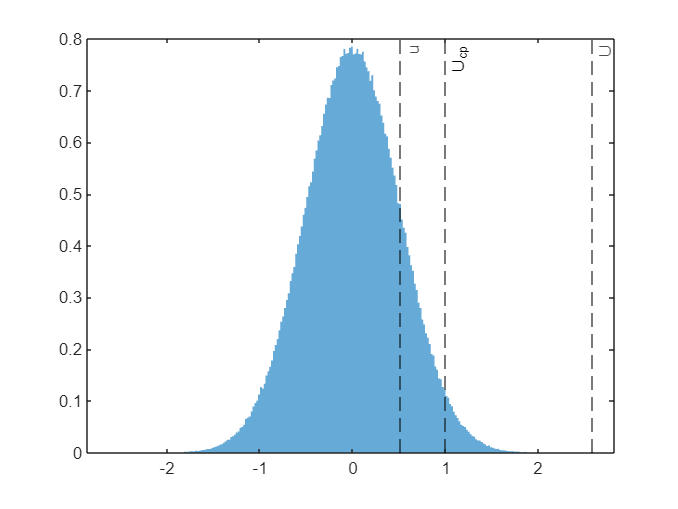

histogram(e3,'Normalization','pdf','EdgeColor','none')
xline(u3_sim,'--k','u')
xline(Ucp3_sim,'--k','U_{cp}')
xline(U3_sim,'--k','U')

4) La pdf è triangolare con WCU = U: *la pdf è convoluzione di due pdf uniformi con WCU = U/2*

*L'errore si può ottenere come somma di due errori indipendenti a distribuzione uniforme identica*

% Generazione di un errore a pdf triangolare come somma di due errori indipendenti a pdf uniforme
U0 = U4/2; % WCU dei due errori indipendenti da sommare
e4a = unifrnd(-U0,U0,[1,Nsim]); % prima componente di e4
e4b = unifrnd(-U0,U0,[1,Nsim]); % seconda componente di e4
e4 =  e4a + e4b;

U4_sim = max(abs(e4))

U4_sim = 0.9993

u4_sim = std(e4)

u4_sim = 0.4077

Ucp4_sim = quantile(e4, (1+cp)/2)

Ucp4_sim = 0.7749

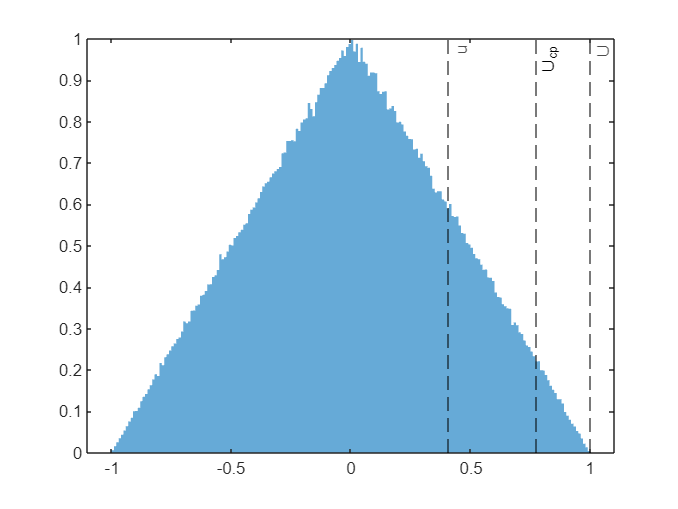

histogram(e4,'Normalization','pdf','EdgeColor','none')
xline(u4_sim,'--k','u')
xline(Ucp4_sim,'--k','U_{cp}')
xline(U4_sim,'--k','U')

5) Pdf arcoseno = *pdf di un errore che nel dominio del tempo segue un andamento sinusoidale*

% Generazione di un errore che segue un andamento sinusoidale
n = [0:Nsim];
Np = 1; % un solo periodo, o un numero intero di periodi
F = Np/Nsim; % frequenza digitale = numero di periodi / numero di campioni
e5 = U5*sin(2*pi*F*n); % la frequenza digitale si moltiplica per n, come la frequenza analogica si moltiplica per t

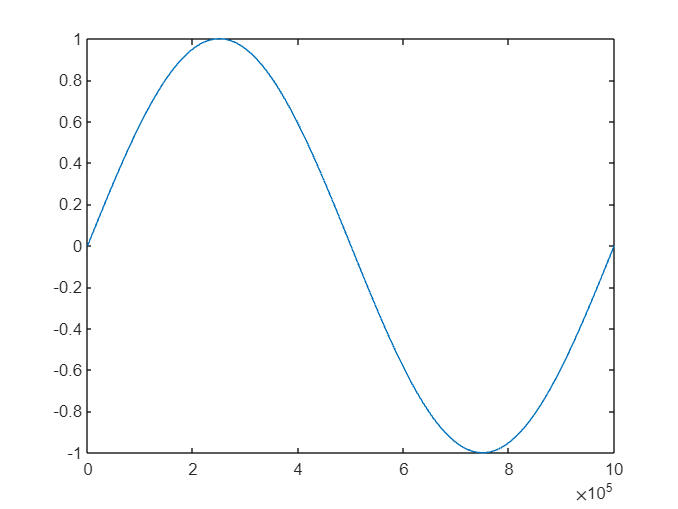

plot(n,e5) % andamento del segnale nel dominio del tempo

U5_sim = max(abs(e5))

U5_sim = 1

u5_sim = std(e5)

u5_sim = 0.7071

Ucp5_sim = quantile(e5, (1+cp)/2)

Ucp5_sim = 0.9969

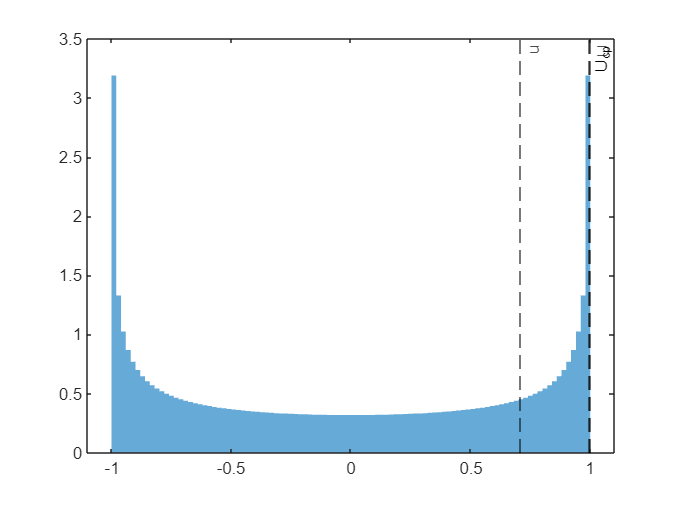

histogram(e5,'Normalization','pdf','EdgeColor','none')
xline(u5_sim,'--k','u')
xline(Ucp5_sim,'--k','U_{cp}')
xline(U5_sim,'--k','U')

6) Pdf convoluzione di tre distribuzioni uniformi identiche

*L'errore si può ottenere come somma di tre errori indipendenti a distribuzione uniforme identica*

U0 = U6/3

U0 = 0.3333

e6a = unifrnd(-U0,U0,[1,Nsim]); % prima componente di e4
e6b = unifrnd(-U0,U0,[1,Nsim]); % seconda componente di e4
e6c = unifrnd(-U0,U0,[1,Nsim]); % terza componente di e4
e6 =  e6a + e6b + e6c;

U6_sim = max(abs(e6))

U6_sim = 0.9940

u6_sim = std(e6)

u6_sim = 0.3334

Ucp6_sim = quantile(e6,(1+cp)/2)

Ucp6_sim = 0.6460

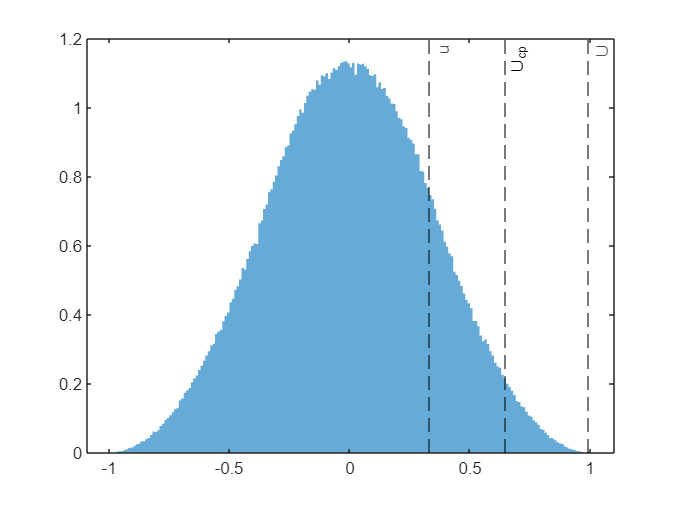

histogram(e6,'Normalization','pdf','EdgeColor','none')
xline(u6_sim,'--k','u')
xline(Ucp6_sim,'--k','U_{cp}')
xline(U6_sim,'--k','U')

## Calcolo di WCU, SU, EU dalla conoscenza di una delle tre

% Proseguimento del quesito precedente.
% Per ogni caso si vuole conoscere WCU, SU, EU, essendo fornita una delle tre.
% WCU, SU, EU devono essere calcolate, naturalmente, senza generare errori simulati.

% Nota:
% Approssimare EU = WCU quando la pdf non è approssimabile a una gaussiana, cioè quando la pdf non è
% "a campana" (più concentrata al centro che ai bordi).
% In generale, per pdf non "a campana", la EU (con cp >= 95%) può essere approssimata con la WCU, e
% quindi:
% 
% Per distribuzioni non a campana, NON HA SENSO USARE UNA EU CON cp >= 0.95: si usa la WCU

% Dati
U1 = 1 % WCU; non sappiamo altro (caso 1)

U1 = 1

u2 = 1

Ucp3 = 1

U4 = 1

U5 = 1

U6 = 1

u2 = 1 % SU; non sappiamo altro (caso 2)
Ucp3 = 1 % EU; non sappiamo altro (caso (3)
U4 = 1 % WCU; la distribuzione è triangolare (caso 4)

cp = 0.9500

U5 = 1 % WCU; la distribuzione è arcoseno (caso 5)
U6 = 1 % WCU; la distribuzione è a campana, convoluzione di tre distribuzioni uniformi identiche (caso 6)

cp = 0.95 % probabilità di copertura per le EU


kcp = 1.9600

% Domande
% kcp % fattore di copertura associato a cp
% U1, u1, Ucp1; U2, u, Ucp2, ecc.: per ogni caso calcolare WCU, SU, EU in base al dato fornito

### Soluzione

kcp = norminv((1+cp)/2) % fattore di copertura di tipo B

U1 = 1

1) E' nota la sola WCU: *la pdf è uniforme (rettangolare)*

*Non si applica l'approssimazione gaussiana*

U1 = U1 % WCU: dato

u1 = 0.5774

u1 = U1/sqrt(3) % SU: dalla WCU per pdf rettangolare

Ucp1 = 1

Ucp1 = U1 % UE approssimata

% Formule esatte per la UE (aggiunte per pignoleria)
Ucp1 = U1*cp % UE esatta

Ucp1 = 0.9500

Ucp1 = unifinv((1+cp)/2,-U1,U1) % UE esatta, applicando la formula della cumulativa

Ucp1 = 0.9500

2) E' nota la sola SU: *la pdf è gaussiana*

u2 = u2 % dato

u2 = 1

U2 = inf % pdf gaussiana

U2 = Inf

Ucp2 = kcp*u2 % pdf gaussiana -> EU = fattore di copertura x SU

Ucp2 = 1.9600

3) E' nota la sola EU: *la pdf è gaussiana, dalla EU si ricava la SU*

Ucp3 = Ucp3 % dato

Ucp3 = 1

u3 = Ucp3/kcp % formula per pdf gaussiana

u3 = 0.5102

U3 = inf % pdf gaussiana

U3 = Inf

4) La pdf è triangolare con WCU = U: *la pdf è convoluzione di due pdf uniformi con WCU = U/2*

*A questo caso l'approssimazione gaussiana è applicabile*

U4 = U4 % dato

U4 = 1

u4 = U4/sqrt(3*2) % u4 = sqrt(2*(U4/2)^2/3) = U4/sqrt(3)/sqrt(2)

u4 = 0.4082

Ucp4 = kcp*u4 % approssimazione gaussiana

Ucp4 = 0.8002

5) Pdf arcoseno = *pdf di un errore che nel dominio del tempo segue un andamento sinusoidale*

*Non si applica l'approssimazione gaussiana*

U5 = U5 % dato

U5 = 1

u5 = U5/sqrt(2) % SU; deriva dal valore efficace del segnale sinusoidale

u5 = 0.7071

Ucp5 = U5 % EU approssimata

Ucp5 = 1

6) Pdf convoluzione di tre distribuzioni uniformi identiche

*A questo caso l'approssimazione gaussiana è applicabile*

U6 = U6 % dato

U6 = 1

u6 = U6/sqrt(3*3) % u6 = sqrt(3*(U6/3)^2/3) = U6/sqrt(3)/sqrt(3)

u6 = 0.3333

Ucp6 = kcp*u6 % approx gaussiana

Ucp6 = 0.6533

## Misure mediante triangolazione (coefficienti di sensibilità assoluti)

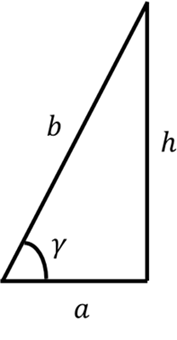

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.
%
% Convenzione:
% x = [a; gamma] % vettore grandezze in ingresso
% theta = [h; b] % vettore grandezze in uscita

### Calcolo simbolico della matrice C (consiglio: da fare a mano all'esame)

Modello della misurazione (da calcolare a mano durante l'esame):

- h = a*tan(gamma)

- b = a/cos(gamma)

clear
syms a gamma real
x = [a;gamma] % variabili di ingresso

$$x = \left(\begin{array}{c} a\\ \gamma \end{array}\right)$$

h = a*tan(gamma); % altezza
b = a/cos(gamma); % distanza dalla sommità
theta = [h;b] % variabili di uscita

$$theta = \left(\begin{array}{c} a\,\tan\left(\gamma \right)\\ \frac{a}{\cos\left(\gamma \right)} \end{array}\right)$$

C = jacobian(theta,x) % matrice jacobiana

$$C = \left(\begin{array}{cc} \tan\left(\gamma \right) & a\,\left({\tan\left(\gamma \right)}^{2}+1\right)\\ \frac{1}{\cos\left(\gamma \right)} & \frac{a\,\sin\left(\gamma \right)}{{\cos\left(\gamma \right)}^{2}} \end{array}\right)$$

### Quesito (il vero quesito da esame)

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.
%
% Convenzione:
% x = [a; gamma] % vettore grandezze in ingresso
% theta = [h; b] % vettore grandezze in uscita

% Dati
clear

a = 10

a = 10

gamma_deg = 75 % angolo in gradi

gamma_deg = 75


Ur_a = 0.01 % incertezza relativa

Ur_a = 0.0100

U_gamma_deg = 0.1 % incertezza assoluta in gradi

U_gamma_deg = 0.1000


cp = 0.95 % probabilità di copertura

cp = 0.9500


% Domande
% h
% b
% U % vettore WCU in ingresso
% u % vettore SU in ingresso
% C % matrice coefficienti di sensibilità
% U_theta % vettore WCU in uscita 
% u_theta % vettore SU in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori sulle grandezze theta(1) e theta(2)
% kmax % massimo fattore di copertura applicabile a theta
% kcp % fattore di copertura per la probabilità di copertura cp
% Ucp_theta % vettore incertezze estese in uscita con probabilità di copertura cp

### Soluzione

gamma = gamma_deg/180*pi % da gradi a radianti

gamma = 1.3090

h = a*tan(gamma)

h = 37.3205

b = a/cos(gamma)

b = 38.6370

U_a = Ur_a*abs(a) % WCU su a

U_a = 0.1000

U_gamma = U_gamma_deg/180*pi % WCU su gamma

U_gamma = 0.0017

U = [U_a; U_gamma] % vettore WCU

U =     0.1000
    0.0017


u = U/sqrt(3) % vettore SU

u =     0.0577
    0.0010


C = [tan(gamma), a*(tan(gamma)^2 + 1); 1/cos(gamma), a*sin(gamma)/cos(gamma)^2] % matrice C

C =     3.7321  149.2820
    3.8637  144.1954


U_theta = abs(C)*U % WCU in uscita

U_theta =     0.6338
    0.6380


Sigma = diag(u)^2 % matrice covarianza in ingresso

Sigma =     0.0033         0
         0    0.0000


Sigma_theta = C*Sigma*C' % propagazione incertezza standard

Sigma_theta =     0.0691    0.0699
    0.0699    0.0709


u_theta = sqrt(diag(Sigma_theta))

u_theta =     0.2628
    0.2662


R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

R_theta =     1.0000    0.9995
    0.9995    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = 0.9995

kmax = U_theta./u_theta

kmax =     2.4117
    2.3967


kcp = norminv((1+cp)/2)

kcp = 1.9600

Ucp_theta = kcp*u_theta

Ucp_theta =     0.5150
    0.5218


### Verifica con metodo Monte Carlo (non richiesta all'esame)

% Calcolare:
% vettori Nsim x 1 degli errori sulle variabili di ingresso, con la pdf appropriata
% vettori Nsim x 1 degli errori sulle variabili di uscita, applicando il modello della misurazione
% le incertezze in uscita, dagli errori Nsim x 1 in uscita
% la matrice dei coefficienti di correlazione in uscita, dagli errori Nsim x 1 in uscita

% Fare anche:
% un istogramma pdf degli errori sulle variabili in uscita
% uno scatterplot degli errori sulle variabili in uscita (notare come lo scatterplot è legato al
% coefficiente di correlazione tra gli errori)

Nsim = 1e6; % numero di simulazioni

e_a = unifrnd(-U_a,U_a,[1,Nsim]); % Nsim errori su a
e_gamma = unifrnd(-U_gamma,U_gamma,[1,Nsim]); % Nsim errori su gamma

a_MC = a + e_a; % Nsim misure di a
gamma_MC = gamma + e_gamma; % Nsim misure di gamma

h_MC = a_MC.*tan(gamma_MC); % Nsim misure di h
b_MC = a_MC./cos(gamma_MC); % Nsim misure di b

e_h = h_MC - h; % Nsim errori di misura su h
e_b = b_MC - b; % Nsim errori di misura su b

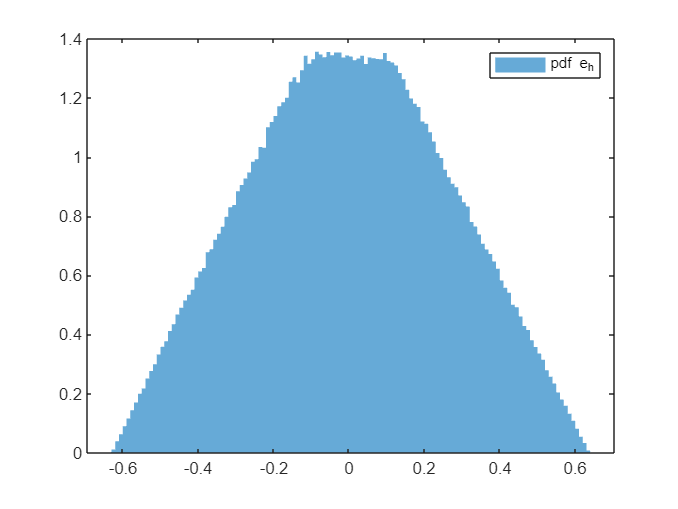

histogram(e_h,'Normalization','pdf','EdgeColor','none')
legend('pdf e_h')

U_h = max(abs(e_h)) % WCU calcolata dagli Nsim errori

U_h = 0.6376

u_h = std(e_h) % SU calcolata dagli Nsim errori

u_h = 0.2627

Ucp_h = quantile(e_h,(1+cp)/2) % EU calcolata dagli Nsim errori

Ucp_h = 0.4964

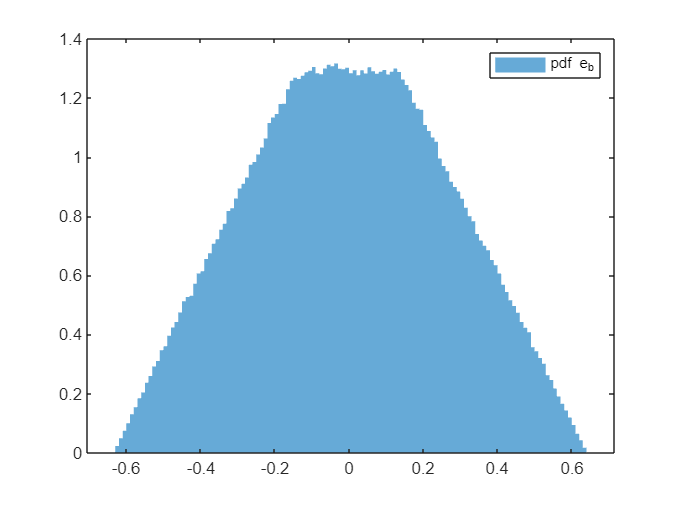

histogram(e_b,'Normalization','pdf','EdgeColor','none')
legend('pdf e_b')

U_b = max(abs(e_b)) % WCU

U_b = 0.6418

u_b = std(e_b) % SU

u_b = 0.2662

Ucp_b = quantile(e_b,(1+cp)/2) % EU

Ucp_b = 0.5007

Scatterplot

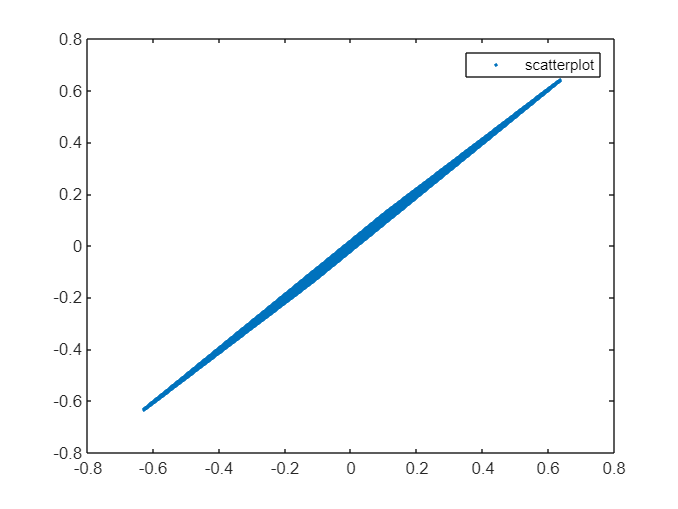

plot(e_h,e_b,'.')
legend('scatterplot')

R_theta_MC = corrcoef(e_h,e_b)

R_theta_MC =     1.0000    0.9995
    0.9995    1.0000


Calcolo manuale del coefficiente di correlazione a partire dai vettori e_h, e_b

e_h

e_h =    -0.1347    0.2025   -0.2843    0.2372    0.2292   -0.1442   -0.2101    0.0280    0.4282   -0.2426    0.0708    0.1500   -0.2376    0.5115    0.3909    0.0513   -0.0031    0.2651    0.3290    0.0534   -0.5769   -0.2877    0.1613   -0.1301    0.3652   -0.1527   -0.1082    0.1648    0.2692    0.0360    0.0690   -0.1089    0.0429    0.2149    0.0025   -0.2228   -0.2476   -0.3955    0.2988    0.0294    0.1348    0.2724   -0.4303   -0.2288   -0.2692   -0.1527    0.0703    0.1561    0.1144    0.3506


e_b

e_b =    -0.1469    0.2097   -0.2912    0.2295    0.2339   -0.1458   -0.2115    0.0294    0.4345   -0.2438    0.0609    0.1497   -0.2450    0.5186    0.3890    0.0688    0.0087    0.2660    0.3379    0.0416   -0.5830   -0.2966    0.1671   -0.1367    0.3617   -0.1400   -0.1191    0.1689    0.2766    0.0339    0.0832   -0.0998    0.0366    0.2246   -0.0000   -0.2378   -0.2617   -0.4007    0.3095    0.0292    0.1303    0.2660   -0.4371   -0.2318   -0.2787   -0.1404    0.0839    0.1601    0.1128    0.3511


sigmaXY = mean(e_h.*e_b) % perché gli errori sono a media nulla

sigmaXY = 0.0699

sigmaX = sqrt(mean(e_h.^2))

sigmaX = 0.2627

sigmaX = std(e_h)

sigmaX = 0.2627

sigmaY = sqrt(mean(e_b.^2))

sigmaY = 0.2662

rhoXY = sigmaXY/(sigmaX*sigmaY)

rhoXY = 0.9995

## Misure mediante triangolazione (coefficienti di sensibilità relativi)

Grandezze in ingresso e in uscita:

- x = [a; gamma] % vettore grandezze in ingresso

- theta = [h; b] % vettore grandezze in uscita

Modello della misurazione:

- h = a*tan(gamma)

- b = a/cos(gamma)

### Calcolo simbolico della matrice Cr

clear
syms a gamma real
x = [a;gamma] % variabili di ingresso

$$x = \left(\begin{array}{c} a\\ \gamma \end{array}\right)$$

h = a*tan(gamma); % altezza
b = a/cos(gamma); % distanza dalla sommità
theta = [h;b] % variabili di uscita

$$theta = \left(\begin{array}{c} a\,\tan\left(\gamma \right)\\ \frac{a}{\cos\left(\gamma \right)} \end{array}\right)$$

Cr = jacobian(log(theta),x).*x' % matrice jacobiana logaritmica

$$Cr = \left(\begin{array}{cc} 1 & \frac{\gamma \,\left({\tan\left(\gamma \right)}^{2}+1\right)}{\tan\left(\gamma \right)}\\ 1 & \frac{\gamma \,\sin\left(\gamma \right)}{\cos\left(\gamma \right)} \end{array}\right)$$

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in
% ingresso sono indipendenti.
% Convenzione:
% x = [a; gamma] % vettore grandezze in ingresso
% theta = [h; b] % vettore in uscita grandezze in uscita

% Dati
clear
a = 10

a = 10

gamma_deg = 75 % angolo in gradi

gamma_deg = 75

Ur_a = 0.01 % incertezza relativa

Ur_a = 0.0100

U_gamma_deg = 0.1 % incertezza assoluta in gradi

U_gamma_deg = 0.1000

cp = 0.95

cp = 0.9500


% Domande
% h
% b
% Ur % vettore WCU relative in ingresso
% ur % vettore SU relative in ingresso
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU relative in uscita 
% ur_theta % vettore SU relative in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

gamma = gamma_deg/180*pi % conversione da gradi a radianti

gamma = 1.3090

h = a*tan(gamma)

h = 37.3205

b = a/cos(gamma)

b = 38.6370

U_gamma = U_gamma_deg/180*pi % conversione da gradi a radianti

U_gamma = 0.0017


Ur_gamma = U_gamma/abs(gamma)

Ur_gamma = 0.0013

Ur = [Ur_a; Ur_gamma]

Ur =     0.0100
    0.0013


ur = Ur/sqrt(3) % perché conosciamo solo la WCU degli errori in ingresso -> pdf uniforme

ur =     0.0058
    0.0008


Cr = [1, (gamma*(tan(gamma)^2 + 1))/tan(gamma); 1, (gamma*sin(gamma))/cos(gamma)] % calcolati a mano

Sigmar = 1.0e-04 *

    0.3333         0
         0    0.0059


Cr =     1.0000    5.2360
    1.0000    4.8852


Ur_theta = abs(Cr)*Ur % propagazione delle WCU

Ur_theta =     0.0170
    0.0165



% ur_theta = Ur_theta/sqrt(3) % ERRORE GRAVE: gli errori in uscita non hanno pdf uniforme, devo
% calcolare la propagazione delle SU

Sigmar = diag(ur)^2 % matrice covarianza degli errori relativi in ingresso

Sigmar = 1.0e-04 *

    0.3333         0
         0    0.0059


Sigmar_theta = Cr*Sigmar*Cr' % propagazione delle SU: matrice covarianza degli errori relativi in uscita

Sigmar_theta = 1.0e-04 *

    0.4958    0.4849
    0.4849    0.4748


ur_theta = sqrt(diag(Sigmar_theta)) % propagazione delle SU: estrazione delle incertezze standard

ur_theta =     0.0070
    0.0069


R_theta = diag(ur_theta)^-1*Sigmar_theta*diag(ur_theta)^-1 % propagazione delle SU: estrazione di R

R_theta =     1.0000    0.9995
    0.9995    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = 0.9995

kmax = Ur_theta./ur_theta % rapporto WCU/SU

kmax =     2.4117
    2.3967


kcp = norminv((1+cp)/2) % fattore di copertura

kcp = 1.9600

Urcp_theta = kcp*ur_theta

Urcp_theta =     0.0138
    0.0135


## Calcolo di modulo e argomento (d,phi) di un numero complesso, date parte reale e immaginaria (a,b) - coefficienti di sensibilità assoluti

Il problema ricorre frequentemente lavorando con le sinusoidi. Se $p$ è il fasore di una sinusoide 

- 
$$\begin{array}{l}
x\left(t\right)=\\
=\mathrm{Re}\left(p\;e^{j\omega \;t} \right)\;\mathrm{forma}\;\mathrm{fasoriale}\\
=d\;\cos \left(\omega \;t+\varphi \;\right)\;\mathrm{forma}\;\mathrm{polare}\\
=a\;\cos \left(\omega \;t\right)-b\;\sin \left(\omega \;t\right)\;\mathrm{forma}\;\mathrm{rettangolare}
\end{array}$$


allora:

- $a,b$ sono le componenti coseno e seno della sinusoide, ovvero le componenti "in fase" e "in quadratura"

- $d,\varphi \;$sono modulo e fase della sinusoide

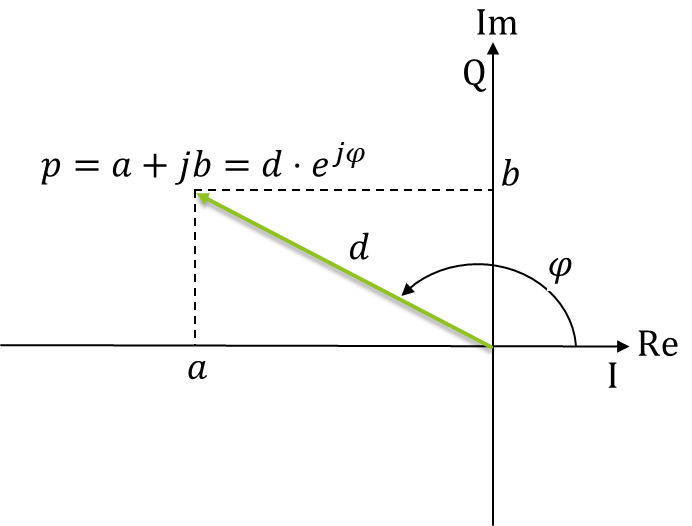

Grandezze in ingresso e in uscita:

- x = [a; b] % vettore grandezze in ingresso

- theta = [d; phi] % vettore grandezze in uscita

Modello della misurazione:

- d = sqrt(a^2+b^2)

- phi = atan2(b,a)

### Calcolo simbolico della matrice C (da fare a mano all'esame)

clear
syms a b real
x = [a; b]

$$x = \left(\begin{array}{c} a\\ b \end{array}\right)$$

d = sqrt(a^2+b^2)

$$d = \sqrt{a^{2}+b^{2}}$$

phi = atan2(b,a)

$$phi = \text{atan2}\left(b,a\right)$$

theta = [d;phi]

$$theta = \left(\begin{array}{c} \sqrt{a^{2}+b^{2}}\\ \text{atan2}\left(b,a\right) \end{array}\right)$$

C = jacobian(theta,x)

$$C = \left(\begin{array}{cc} \frac{a}{\sqrt{a^{2}+b^{2}}} & \frac{b}{\sqrt{a^{2}+b^{2}}}\\ -\frac{b}{a^{2}+b^{2}} & \frac{a}{a^{2}+b^{2}} \end{array}\right)$$

C = simplify(jacobian(theta,x)) % in questo caso simplify non fa nulla

$$C = \left(\begin{array}{cc} \frac{a}{\sqrt{a^{2}+b^{2}}} & \frac{b}{\sqrt{a^{2}+b^{2}}}\\ -\frac{b}{a^{2}+b^{2}} & \frac{a}{a^{2}+b^{2}} \end{array}\right)$$

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
a = -10

a = -10

b = -15

b = -15

U_a = 0.01

U_a = 0.0100

U_b = 0.01

U_b = 0.0100

cp = 0.95

cp = 0.9500


% Domande
% d
% phi
% U % vettore WCU in ingresso
% u % vettore SU in ingresso
% C % matrice coefficienti di sensibilità
% U_theta % vettore WCU in uscita 
% u_theta % vettore SU in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Ucp_theta % vettore incertezze estese in uscita con probabilità di copertura cp

### Soluzione

d = sqrt(a^2+b^2)

d = 18.0278

phi = atan2(b,a)

phi = -2.1588

U = [U_a; U_b] % vettore delle WCU

U =     0.0100
    0.0100


u = U/sqrt(3) % vettore delle SU

u =     0.0058
    0.0058


C = [a/d, b/d; -b/d^2, a/d^2]

C =    -0.5547   -0.8321
    0.0462   -0.0308


U_theta = abs(C)*U % WCU in uscita

U_theta =     0.0139
    0.0008


Sigma = diag(u)^2 % matrice covarianza in ingresso

Sigma = 1.0e-04 *

    0.3333         0
         0    0.3333


Sigma_theta = C*Sigma*C' % propagazione

Sigma_theta = 1.0e-04 *

    0.3333   -0.0000
   -0.0000    0.0010


u_theta = sqrt(diag(Sigma_theta)) 

u_theta =     0.0058
    0.0003


R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

R_theta =     1.0000   -0.0000
   -0.0000    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = -5.7263e-17

kmax = U_theta./u_theta

kmax =     2.4019
    2.4019


kcp = norminv((1+cp)/2)

kcp = 1.9600

Ucp_theta = kcp*u_theta

Ucp_theta =     0.0113
    0.0006


### Verifica con metodo Monte Carlo

Generazione errori MC in ingresso (1 x Nsim)

Nsim = 1e6;
e_a = unifrnd(-U_a,U_a,[1,Nsim])

e_a =    -0.0043   -0.0078   -0.0072   -0.0095    0.0065   -0.0038   -0.0018   -0.0051    0.0080   -0.0043   -0.0075   -0.0052    0.0073   -0.0039    0.0050    0.0062    0.0083    0.0054   -0.0077   -0.0095   -0.0087   -0.0042    0.0037    0.0028    0.0078   -0.0042   -0.0018    0.0091    0.0060   -0.0086    0.0068   -0.0051    0.0037   -0.0009    0.0028   -0.0034   -0.0017    0.0091   -0.0087    0.0013   -0.0076   -0.0075    0.0020   -0.0063   -0.0077    0.0016    0.0048    0.0089   -0.0047    0.0071


e_b = unifrnd(-U_b,U_b,[1,Nsim])

e_b =     0.0067    0.0009    0.0044   -0.0059   -0.0008    0.0033   -0.0027    0.0040   -0.0084   -0.0071   -0.0004    0.0074   -0.0045   -0.0074   -0.0040    0.0001   -0.0068    0.0058   -0.0025    0.0045   -0.0005    0.0034   -0.0052    0.0041    0.0011    0.0008   -0.0047    0.0098   -0.0020    0.0028    0.0087   -0.0050    0.0043   -0.0002   -0.0043    0.0012    0.0012    0.0035   -0.0099    0.0098   -0.0026    0.0044    0.0016   -0.0033    0.0058   -0.0097   -0.0099   -0.0095    0.0069    0.0007


Generazione grandezze misurate in ingresso (1 x Nsim)

a_MC = a + e_a

a_MC =   -10.0043  -10.0078  -10.0072  -10.0095   -9.9935  -10.0038  -10.0018  -10.0051   -9.9920  -10.0043  -10.0075  -10.0052   -9.9927  -10.0039   -9.9950   -9.9938   -9.9917   -9.9946  -10.0077  -10.0095  -10.0087  -10.0042   -9.9963   -9.9972   -9.9922  -10.0042  -10.0018   -9.9909   -9.9940  -10.0086   -9.9932  -10.0051   -9.9963  -10.0009   -9.9972  -10.0034  -10.0017   -9.9909  -10.0087   -9.9987  -10.0076  -10.0075   -9.9980  -10.0063  -10.0077   -9.9984   -9.9952   -9.9911  -10.0047   -9.9929


b_MC = b + e_b

b_MC =   -14.9933  -14.9991  -14.9956  -15.0059  -15.0008  -14.9967  -15.0027  -14.9960  -15.0084  -15.0071  -15.0004  -14.9926  -15.0045  -15.0074  -15.0040  -14.9999  -15.0068  -14.9942  -15.0025  -14.9955  -15.0005  -14.9966  -15.0052  -14.9959  -14.9989  -14.9992  -15.0047  -14.9902  -15.0020  -14.9972  -14.9913  -15.0050  -14.9957  -15.0002  -15.0043  -14.9988  -14.9988  -14.9965  -15.0099  -14.9902  -15.0026  -14.9956  -14.9984  -15.0033  -14.9942  -15.0097  -15.0099  -15.0095  -14.9931  -14.9993


Generazione grandezze misurate in uscita (1 x Nsim)

*Si applica semplicemente il modello della misurazione alle grandezze misurate in ingresso*

d_MC = sqrt(a_MC.^2+b_MC.^2)

d_MC =    18.0246   18.0313   18.0281   18.0380   18.0248   18.0271   18.0310   18.0273   18.0303   18.0361   18.0322   18.0245   18.0274   18.0360   18.0283   18.0242   18.0289   18.0199   18.0340   18.0293   18.0330   18.0272   18.0300   18.0228   18.0225   18.0294   18.0326   18.0145   18.0261   18.0302   18.0168   18.0348   18.0222   18.0284   18.0298   18.0287   18.0277   18.0198   18.0409   18.0188   18.0342   18.0283   18.0253   18.0340   18.0272   18.0349   18.0334   18.0307   18.0246   18.0232


phi_MC = atan2(b_MC,a_MC)

phi_MC =    -2.1592   -2.1592   -2.1593   -2.1591   -2.1585   -2.1591   -2.1588   -2.1592   -2.1582   -2.1588   -2.1591   -2.1593   -2.1583   -2.1588   -2.1584   -2.1585   -2.1582   -2.1587   -2.1591   -2.1594   -2.1592   -2.1591   -2.1585   -2.1588   -2.1585   -2.1590   -2.1587   -2.1587   -2.1585   -2.1593   -2.1588   -2.1589   -2.1588   -2.1588   -2.1585   -2.1590   -2.1589   -2.1585   -2.1589   -2.1590   -2.1591   -2.1593   -2.1588   -2.1590   -2.1593   -2.1584   -2.1583   -2.1581   -2.1592   -2.1585


Calcolo errori MC in uscita (1 x Nsim)

e_d = d_MC - d

e_d =    -0.0032    0.0036    0.0003    0.0102   -0.0029   -0.0006    0.0032   -0.0005    0.0026    0.0083    0.0045   -0.0032   -0.0003    0.0083    0.0005   -0.0035    0.0011   -0.0078    0.0063    0.0015    0.0053   -0.0005    0.0023   -0.0050   -0.0052    0.0017    0.0049   -0.0132   -0.0016    0.0025   -0.0110    0.0070   -0.0056    0.0007    0.0020    0.0009   -0.0001   -0.0079    0.0131   -0.0089    0.0064    0.0005   -0.0025    0.0062   -0.0006    0.0072    0.0056    0.0030   -0.0032   -0.0046


e_phi = phi_MC - phi

e_phi = 1.0e-03 *

   -0.4070   -0.3890   -0.4698   -0.2565    0.3257   -0.2789   -0.0010   -0.3574    0.6284    0.0218   -0.3336   -0.4695    0.4775    0.0461    0.3545    0.2823    0.5915    0.0683   -0.2779   -0.5762   -0.3870   -0.2977    0.3289    0.0031    0.3238   -0.2207    0.0610    0.1193    0.3389   -0.4838    0.0471   -0.0824    0.0389   -0.0361    0.2591   -0.1908   -0.1172    0.3120   -0.0978   -0.2417   -0.2691   -0.4803    0.0444   -0.1905   -0.5347    0.3710    0.5272    0.7047   -0.4288    0.3061


Visualizzazione dell'errore su 1a grandezza in uscita (d)

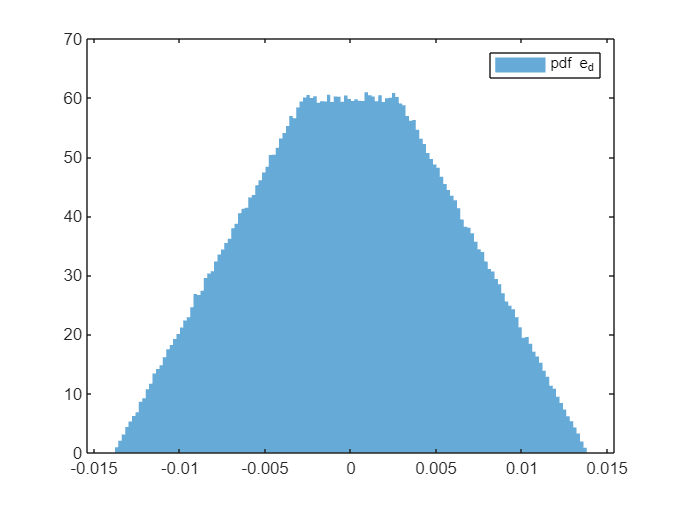

histogram(e_d,'Normalization','pdf','EdgeColor','none')
legend('pdf e_d')

Calcolo incertezze WCU, SU, EU dalla popolazione di errori in uscita

U_d = max(abs(e_d))

U_d = 0.0139

u_d = std(e_d)

u_d = 0.0058

Ucp_d = quantile(e_d,(1+cp)/2)

Ucp_d = 0.0108

Visualizzazione dell'errore su 2a grandezza in uscita (phi)

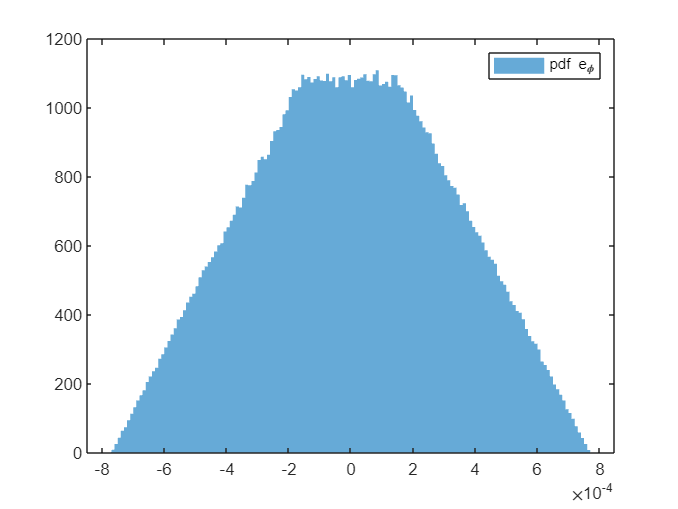

histogram(e_phi,'Normalization','pdf','EdgeColor','none')
legend('pdf e_\phi')

U_phi = max(abs(e_phi))

U_phi = 7.6908e-04

u_phi = std(e_phi)

u_phi = 3.2041e-04

Ucp_phi = quantile(e_phi,(1+cp)/2)

Ucp_phi = 6.0099e-04

Scatterplot (rappresentazione grafica strettamente collegata al coefficiente di correlazione)

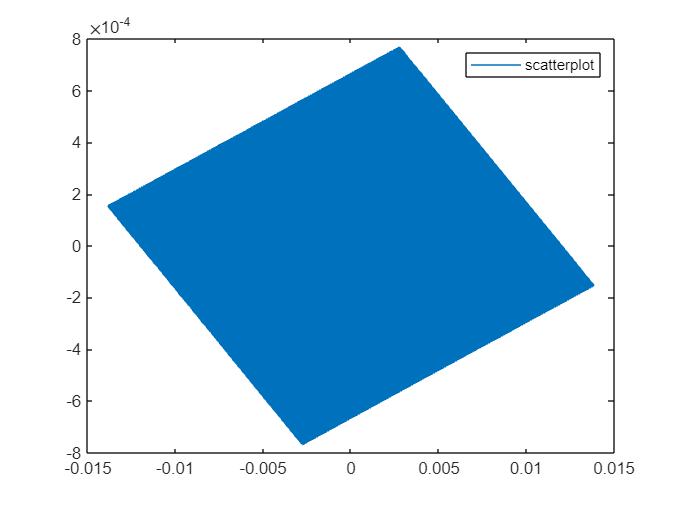

plot(e_d,e_phi)
legend('scatterplot')

R_theta_MC = corrcoef(e_d,e_phi)

R_theta_MC =     1.0000   -0.0001
   -0.0001    1.0000


## Calcolo di parte reale e immaginaria (a,b) di un numero complesso, dati modulo e argomento (d,phi) - coefficienti di sensibilità assoluti

Grandezze in ingresso e in uscita:

- x = [d; phi] % vettore grandezze in ingresso

- theta = [a; b] % vettore in uscita grandezze in uscita

Modello della misurazione:

- a = d*cos(phi)

- b = d*sin(phi)

### Calcolo simbolico della matrice C (da fare a mano all'esame)

clear
syms d phi real
x = [d; phi]

$$x = \left(\begin{array}{c} d\\ \varphi \end{array}\right)$$

a = d*cos(phi)

$$a = d\,\cos\left(\varphi \right)$$

b = d*sin(phi)

$$b = d\,\sin\left(\varphi \right)$$


theta = [a;b]

$$theta = \left(\begin{array}{c} d\,\cos\left(\varphi \right)\\ d\,\sin\left(\varphi \right) \end{array}\right)$$

C = jacobian(theta,x)

$$C = \left(\begin{array}{cc} \cos\left(\varphi \right) & -d\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right) & d\,\cos\left(\varphi \right) \end{array}\right)$$

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
d = 10

d = 10

phi_deg = 165

phi_deg = 165

Ur_d = 0.01 % incertezza relativa

Ur_d = 0.0100

Ur_phi = 0.01 % incertezza relativa

Ur_phi = 0.0100

cp = 0.95

cp = 0.9500


% Domande
% a
% b
% U % vettore WCU in ingresso
% u % vettore SU in ingresso
% C % matrice coefficienti di sensibilità
% U_theta % vettore WCU in uscita 
% u_theta % vettore SU in uscita
% R_theta % matrice coefficienti di correlazione in uscita
% rho_theta_12 % coefficiente di correlazione tra gli errori in uscita sulle grandezze theta(1) e theta(2)
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Ucp_theta % vettore incertezze estese in uscita con probabilità di copertura cp

### Soluzione

phi = phi_deg/180*pi % passaggio da gradi a radianti

phi = 2.8798

a = d*cos(phi)

a = -9.6593

b = d*sin(phi)

b = 2.5882

Passaggio da incertezze relative a incertezze assolute

*Perché voglio utilizzare i coefficienti di sensibilità assoluti*

U_d = Ur_d*abs(d)

U_d = 0.1000

U_phi = Ur_phi*abs(phi)

U_phi = 0.0288

U = [U_d; U_phi] % WCU in ingresso

U =     0.1000
    0.0288


u = U/sqrt(3) % SU in ingresso

u =     0.0577
    0.0166


C = [cos(phi), -d*sin(phi); sin(phi), d*cos(phi)]

C =    -0.9659   -2.5882
    0.2588   -9.6593


U_theta = abs(C)*U % WCU in uscita (errori in ingresso indipendenti)

U_theta =     0.1711
    0.3040


Sigma = diag(u)^2 % matrice covarianza in ingresso (errori in ingresso incorrelati)

Sigma =     0.0033         0
         0    0.0003


Sigma_theta = C*Sigma*C'% propagazione

Sigma_theta =     0.0050    0.0061
    0.0061    0.0260


u_theta = sqrt(diag(Sigma_theta)) % SU in uscita

u_theta =     0.0704
    0.1613


R_theta = diag(u_theta)^-1*Sigma_theta*diag(u_theta)^-1

R_theta =     1.0000    0.5349
    0.5349    1.0000


rho_theta_12 = R_theta(1,2)

rho_theta_12 = 0.5349

kmax = U_theta./u_theta

kmax =     2.4294
    1.8851


kcp = norminv((1+cp)/2)

kcp = 1.9600

Ucp_theta = kcp*u_theta

Ucp_theta =     0.1381
    0.3161


### Verifica con metodo Monte Carlo

Nsim = 1e6;

Generazione errori MC in ingresso

e_d = unifrnd(-U_d,U_d,[1,Nsim]);
e_phi = unifrnd(-U_phi,U_phi,[1,Nsim]);

Generazione misure MC in ingresso

d_MC = d + e_d;
phi_MC = phi + e_phi;

Calcolo misure MC in uscita

a_MC = d_MC.*cos(phi_MC);
b_MC = d_MC.*sin(phi_MC);

Calcolo errori MC in uscita

e_a = a_MC - a;
e_b = b_MC - b;

Analisi errore sulla 1a grandezza in uscita (a)

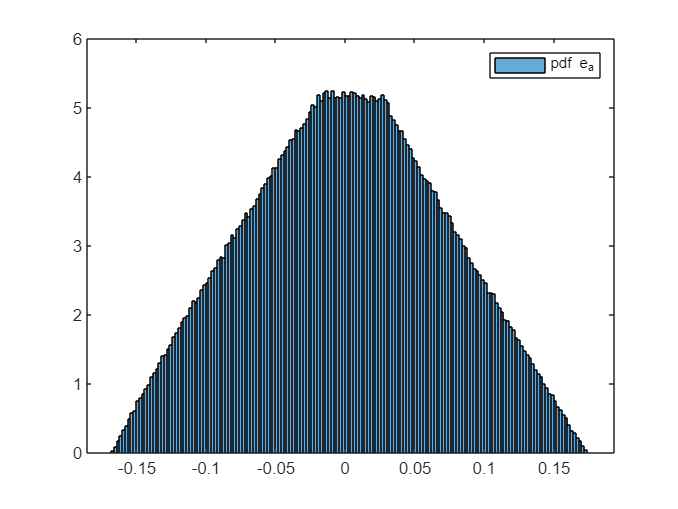

histogram(e_a,'Normalization','pdf')
legend('pdf e_a')

U_a = max(abs(e_a))

U_a = 0.1741

u_a = std(e_a)

u_a = 0.0705

Ucp_a = quantile(e_a,(1+cp)/2)

Ucp_a = 0.1349

Analisi errore sulla 2a grandezza in uscita (b)

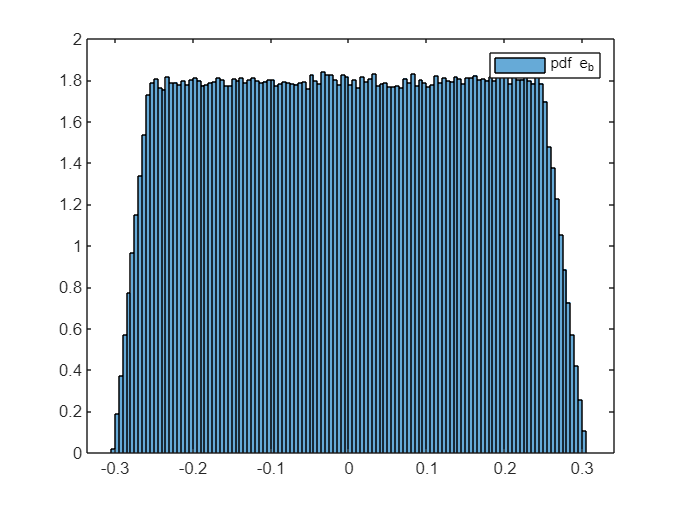

histogram(e_b,'Normalization','pdf')
legend('pdf e_b')

U_b = max(abs(e_b))

U_b = 0.3055

u_b = std(e_b)

u_b = 0.1613

Ucp_b = quantile(e_b,(1+cp)/2) % non coincide con quella calcolata con l'approx gaussiana

Ucp_b = 0.2660

Scatterplot (legato al coefficiente di correlazione)

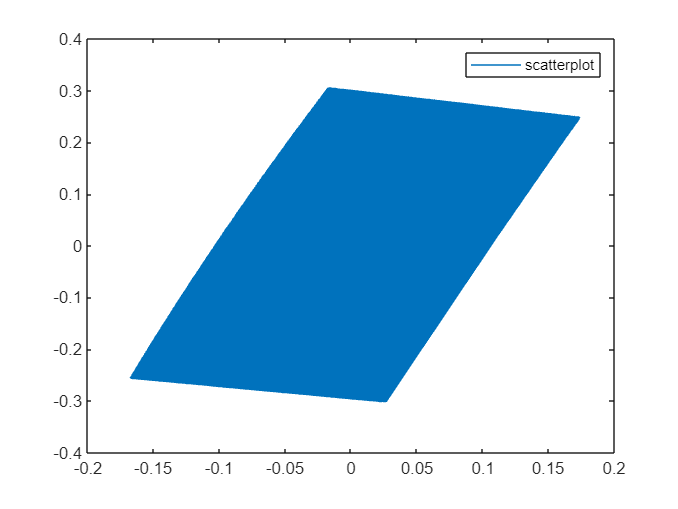

plot(e_a,e_b)
legend('scatterplot')

R_MC = corrcoef(e_a,e_b)

R_MC =     1.0000    0.5348
    0.5348    1.0000


## Misura del raggio terrestre col metodo di Eratostene (coefficienti di sensibilità relativi)

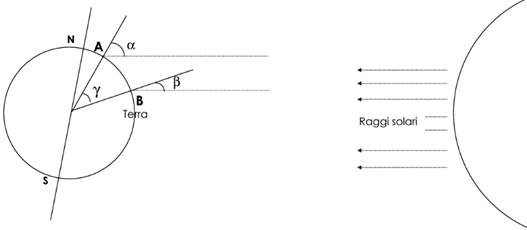 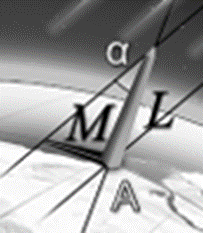

Le relazioni che danno il raggio terrestre sono le seguenti:

$\alpha =\textrm{atan}{\left(\frac{M_a }{L_a }\right)}$ angolo di incidenza dei raggi solari nella città A

$\beta =\textrm{atan}{\left(\frac{M_b }{L_b }\right)}$ angolo di incidenza dei raggi solari nella città B

$\gamma =\ \alpha -\beta$ angolo tra la città A e la città B

$C=D\frac{2\pi }{\gamma }$ circonferenza terrestre ($D$ = distanza tra le città A e B)

$R=\frac{C}{2\pi \;}$ raggio terrestre

In definitiva:


$$R=\frac{D}{\textrm{atan}{\left(\frac{M_a }{L_a }\right)}-\textrm{atan}{\left(\frac{M_b }{L_b }\right)}}$$


### Calcolo simbolico della matrice Cr

clear
syms D Ma La Mb Lb real positive
x = [D; Ma; La; Mb; Lb] % variabili di ingresso, nell'ordine scelto

alpha = atan(Ma/La);
beta = atan(Mb/Lb);
gamma = alpha - beta;
C = D*2*pi/gamma;
R = C/(2*pi);

theta = R % variabili di uscita, nell'ordine scelto

C_r = simplify(jacobian(log(theta),x).*x')

### Quesito (le derivate sono un po' troppo complesse per essere richieste all'esame)

All'esame non ci saranno problemi con derivate così complesse: lo scopo del corso e dell'esame è un'altro

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
D = 389 % distanza Enna - Caserta (km)
La = 1 % lunghezza gnomone Enna (m)
Ma = 1.658 % lunghezza ombra Enna (m)
Lb = 1 % lunghezza gnomone Caserta (m)
Mb = 1.45 % lunghezza ombra Caserta (m)

Ur_D = 0.01 % incertezza relative di D
Ur0 = 0.001 % incertezza relativa delle altre misure in ingresso

cp = 0.95

% Domande
% R % misura in uscita
% Ur % vettore WCU in ingresso relative
% ur % vettore SU in ingresso relative
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU in uscita relative
% ur_theta % vettore SU in uscita relative
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

alpha = atan(Ma/La);
beta = atan(Mb/Lb);
gamma = alpha - beta;
C = D*2*pi/gamma;
R = C/(2*pi)

Ur = [Ur_D; Ur0; Ur0; Ur0; Ur0] % 5 misure in ingresso
ur = Ur/sqrt(3)

% Scriviamo Cr presupponendo x = [D; Ma; La; Mb; Lb]
s1 = (Lb*Mb)/((atan(La/Ma) - atan(Lb/Mb))*(Lb^2 + Mb^2));
s2 = (La*Ma)/((atan(La/Ma) - atan(Lb/Mb))*(La^2 + Ma^2));
Cr = [1, s2, -s2, -s1, s1]

% Copia e incolla da Matlab
Cr = [1, (La*Ma)/((atan(La/Ma) - atan(Lb/Mb))*(La^2 + Ma^2)), -(La*Ma)/((atan(La/Ma) - atan(Lb/Mb))*(La^2 + Ma^2)), -(Lb*Mb)/((atan(La/Ma) - atan(Lb/Mb))*(Lb^2 + Mb^2)), (Lb*Mb)/((atan(La/Ma) - atan(Lb/Mb))*(Lb^2 + Mb^2))]

Ur_theta = abs(Cr)*Ur

% SU: metodo semplice, per errori di ingresso incorrelati e una sola variabile di uscita
ur_theta = sqrt(Cr.^2*ur.^2) 

% SU: metodo generale
Sigmar = diag(ur)^2;
Sigmar_theta = Cr*Sigmar*Cr';
ur_theta = sqrt(diag(Sigmar_theta))

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
er_D = unifrnd(-Ur_D,Ur_D,[1,Nsim]);
er_Ma = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_La = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_Mb = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_Lb = unifrnd(-Ur0,Ur0,[1,Nsim]);

D_MC = D*(1 + er_D); % o anche D + er_D*D
Ma_MC = Ma*(1 + er_Ma);
La_MC = La*(1 + er_La);
Mb_MC = Mb*(1 + er_Mb);
Lb_MC = Lb*(1 + er_Lb);

alpha_MC = atan(Ma_MC./La_MC);
beta_MC = atan(Mb_MC./Lb_MC);
gamma_MC = alpha_MC - beta_MC;
C_MC = D_MC*2*pi./gamma_MC;
R_MC = C_MC/(2*pi)

er_R = (R_MC - R)/R

histogram(er_R,'Normalization','pdf','EdgeColor','none')
legend('pdf e_{r,R}')

br_R = mean(er_R)

Ur_R = max(abs(er_R))
ur_R = std(er_R)
Urcp_R = quantile(er_R,(1+cp)/2)

## Misura di capacità mediante risposta al gradino di circuito RC

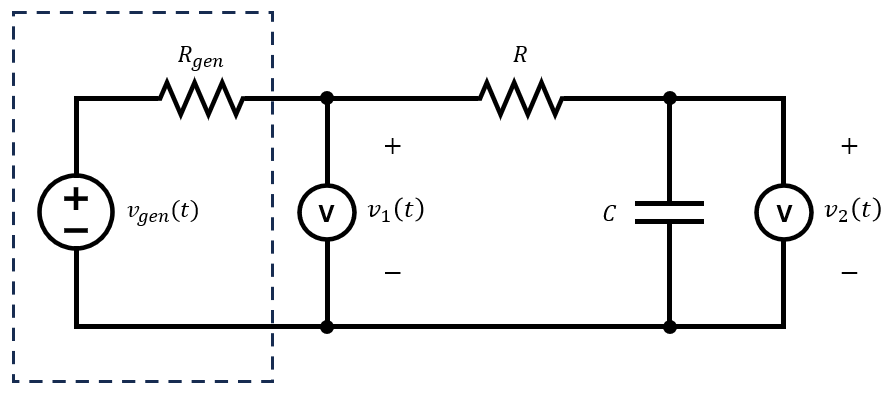

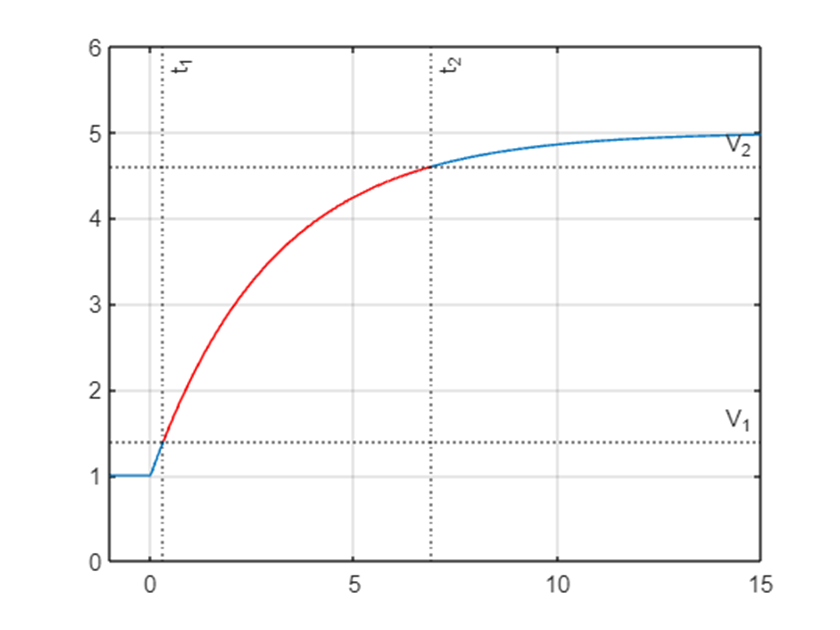

Sappiamo che:


$$t_r =\tau \;\;\log \left(9\right)$$



$$C_{tr} =\frac{t_r }{{\left(R+R_{gen} \right)}\cdot \log \left(9\right)\;}$$


### Calcolo simbolico della matrice Cr

clear
syms t_r R R_gen real
x = [t_r; R; R_gen]

C_tr = t_r/((R+R_gen)*log(sym(9))) % se si scrive log(9) si ottengono risultati "brutti"

theta = C_tr;

C = simplify(jacobian(theta,x)) % coefficienti sensibilità assoluti
C_r = simplify(jacobian(log(theta),x).*x') % coefficienti sensibilità assoluti

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
Rgen = 50
R = 100
tr = 155e-9 % ns

Ur0 = 0.01 % incertezza relativa su tutte le misure

cp = 0.95

% Domande
% Ctr % misura in uscita
% Ur % vettore WCU in ingresso relative
% ur % vettore SU in ingresso relative
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU in uscita relative
% ur_theta % vettore SU in uscita relative
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

Ctr = tr/((R+Rgen)*log(9))

Ur = [Ur0; Ur0; Ur0] % 3 misure in ingresso
Ur = Ur0*ones(3,1)
ur = Ur/sqrt(3)

% Scriviamo Cr presupponendo x = [tr; R; Rgen]
Cr = [1, -R/(R + Rgen), -Rgen/(R + Rgen)]

Ur_theta = abs(Cr)*Ur

% SU: metodo semplice, per errori di ingresso incorrelati e una sola variabile di uscita
ur_theta = sqrt(Cr.^2*ur.^2) 

% SU: metodo generale
Sigmar = diag(ur)^2;
Sigmar_theta = Cr*Sigmar*Cr';
ur_theta = sqrt(diag(Sigmar_theta))

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
er_tr = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_R = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_Rgen = unifrnd(-Ur0,Ur0,[1,Nsim]);

tr_MC = tr*(1 + er_tr); % o anche tr + er_tr*tr
R_MC = R*(1 + er_R);
Rgen_MC = Rgen*(1 + er_Rgen);

C_MC = tr_MC./((R_MC+Rgen_MC)*log(9));

er_C = (C_MC - Ctr)/Ctr

histogram(er_C,'Normalization','pdf','EdgeColor','none')
legend('pdf e_{r,C}')

br_tr = mean(er_C)

Ur_tr = max(abs(er_C))
ur_tr = std(er_C)
Urcp_tr = quantile(er_C,(1+cp)/2)

## Misura di capacità mediante risposta di ampiezza single-tone di circuito RC

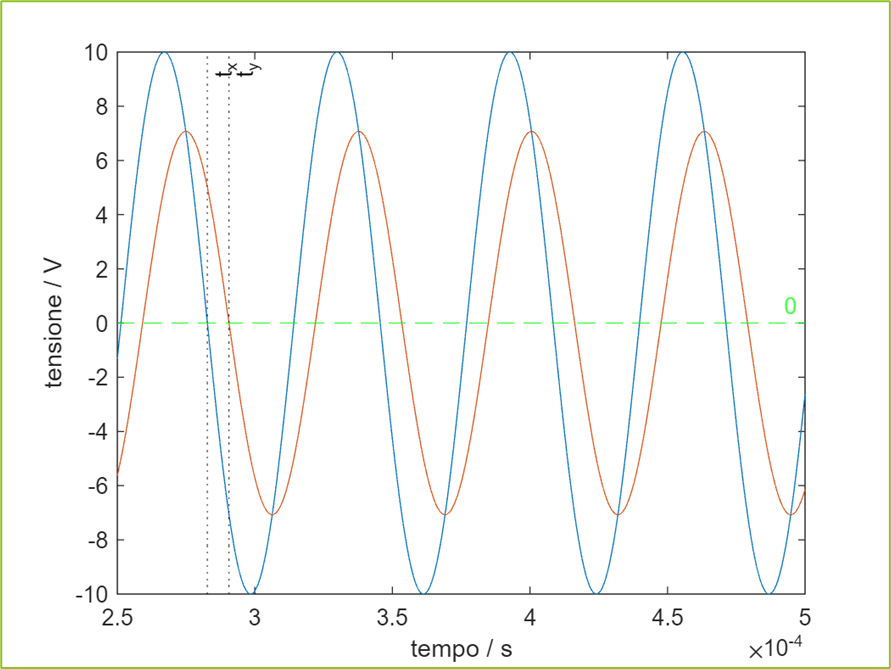

Sappiamo che:


$$H=\frac{V_{\textrm{pp},\textrm{out}} }{V_{\textrm{pp},\textrm{in}} }$$



$$H=\frac{1}{\sqrt{1+{\left(\frac{f}{f_c }\right)}^2 \;}}$$



$$f_{c\;} =\frac{1}{2\pi \;\tau \;}=\frac{1}{2\pi \;R\;C}$$



$$C_H =\frac{\sqrt{1-H^2 \;}}{H}\;\frac{1}{2\pi \;R\;f}$$


### Calcolo simbolico della matrice Cr

clear
syms H f R real
x = [H; f; R]

C_H = 1/(2*pi*R*f)*sqrt(1-H^2)/H % misura di capacità da risposta di ampiezza single-tone
theta = C_H;

C = simplify(jacobian(theta,x)) % coefficienti sensibilità assoluti
C_r = simplify(jacobian(log(theta),x).*x')

### Quesito

% Si calcolino le grandezze in uscita e le loro incertezze, in base ai dati sulle grandezze in ingresso. 
% Gli errori in ingresso sono indipendenti.

% Dati
clear
Rgen = 50
R = 100
f = 100e3
H = 0.32

Ur0 = 0.01 % incertezza relativa su tutte le misure

cp = 0.95

% Domande
% Ctr % misura in uscita
% Ur % vettore WCU in ingresso relative
% ur % vettore SU in ingresso relative
% Cr % matrice coefficienti di sensibilità relativi
% Ur_theta % vettore WCU in uscita relative
% ur_theta % vettore SU in uscita relative
% kcp % fattore di copertura per la probabilità di copertura cp
% kmax % massimo fattore di copertura applicabile 
% Urcp_theta % vettore incertezze estese relative in uscita con probabilità di copertura cp

### Soluzione

CH = 1/(2*pi*R*f)*sqrt(1-H^2)/H

Ur = [Ur0; Ur0; Ur0] % 3 misure in ingresso
Ur = Ur0*ones(3,1)
ur = Ur/sqrt(3)

% Scriviamo Cr presupponendo x = [H; f; R]
Cr = [1/(H^2 - 1), -1, -1]

Ur_theta = abs(Cr)*Ur

% SU: metodo semplice, per errori di ingresso incorrelati e una sola variabile di uscita
ur_theta = sqrt(Cr.^2*ur.^2) 

% SU: metodo generale
Sigmar = diag(ur)^2;
Sigmar_theta = Cr*Sigmar*Cr';
ur_theta = sqrt(diag(Sigmar_theta))

kmax = Ur_theta./ur_theta
kcp = norminv((1+cp)/2)
Urcp_theta = kcp*ur_theta

### Verifica con metodo Monte Carlo

Nsim = 1e6;
er_H = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_f = unifrnd(-Ur0,Ur0,[1,Nsim]);
er_R = unifrnd(-Ur0,Ur0,[1,Nsim]);

H_MC = H*(1 + er_H); % o anche tr + er_tr*tr
f_MC = f*(1 + er_f);
R_MC = R*(1 + er_R);

C_MC = 1./(2*pi*R_MC.*f_MC).*sqrt(1-H_MC.^2)./H_MC;

er_C = (C_MC - CH)/CH

histogram(er_C,'Normalization','pdf','EdgeColor','none')
legend('pdf e_{r,C}')

br_C = mean(er_C)

Ur_C = max(abs(er_C))
ur_C = std(er_C)
Urcp_C = quantile(er_C,(1+cp)/2)